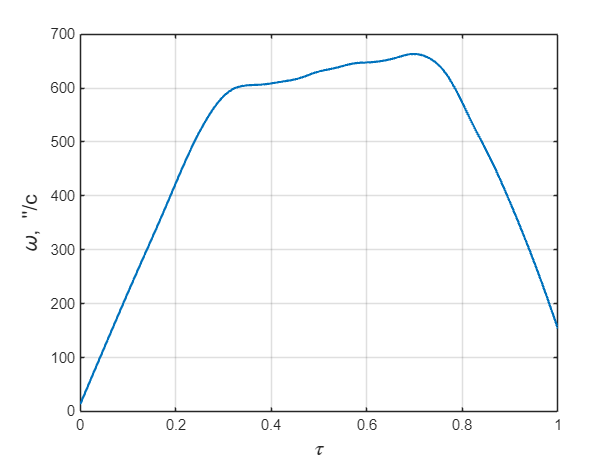

data = importfile("6.txt");


vv = smooth(data.V, 0.3, 'loess');
vv = (vv+30)*8.6;
t = linspace(0,1,length(vv));
figure
plot(t,vv,"LineWidth",1.5);
grid on
xlabel('$\tau$','Interpreter','latex','FontSize',14)
ylabel("\omega, ''/c",'FontSize',14)
print(gcf, '../img/oz-gyro.png', '-dpng', '-r600')

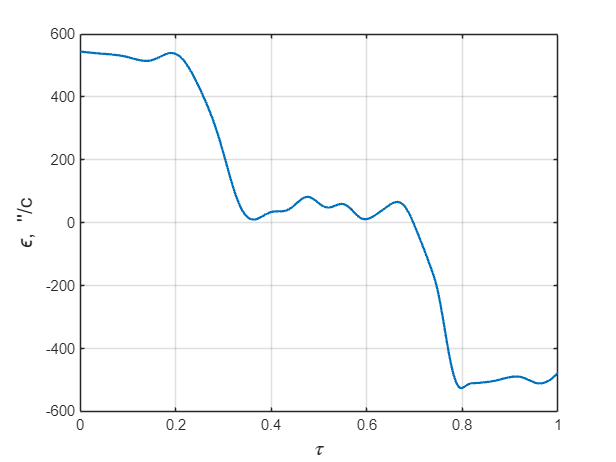

a = diff(vv)/0.01;
a = [a; a(end)];
a(300:end) = -a(1:88)*0.95;
a(300) = -550;
a = smooth(a, 0.1, 'loess');
figure
plot(t,a, "LineWidth",1.5);
grid on
xlabel('$\tau$','Interpreter','latex','FontSize',14)
ylabel("\epsilon, ''/c", "FontSize",14)
print(gcf, '../img/oz-gyro-acc.png', '-dpng', '-r600')

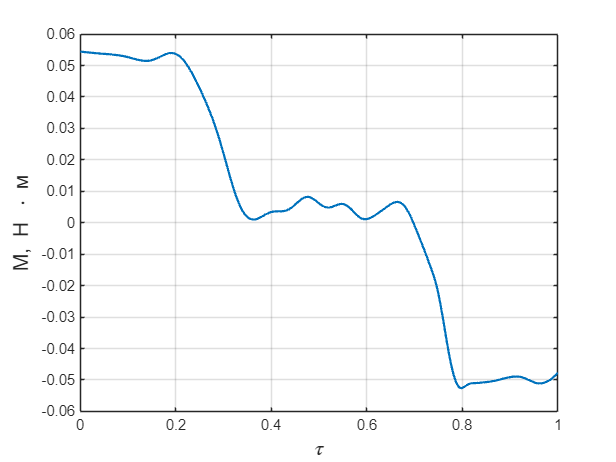

figure
plot(t,a/50 * 0.005, "LineWidth",1.5);
grid on
xlabel('$\tau$','Interpreter','latex','FontSize',14)
ylabel("M, Н \cdot м", "FontSize",14)
yticks(-0.06:0.01:0.06)
print(gcf, '../img/oz-gyro-mom.png', '-dpng', '-r600')

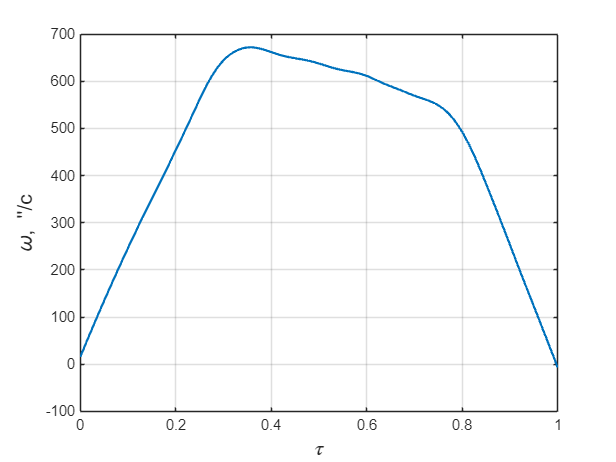

clear
clc

data = importfile("8.txt");


vv = smooth(data.V, 0.3, 'loess');
vv = (vv)*11.5;
vv = vv(1:355);
t = linspace(0,1,length(vv));
figure
plot(t,vv,"LineWidth",1.5);
grid on
xlabel('$\tau$','Interpreter','latex','FontSize',14)
ylabel("\omega, ''/c",'FontSize',14)
print(gcf, '../img/oy-gyro.png', '-dpng', '-r600')

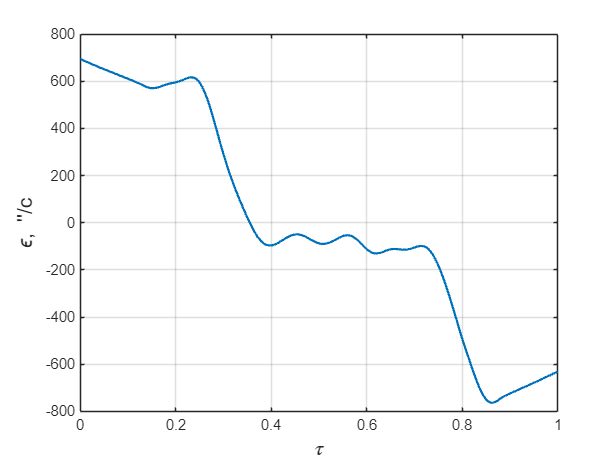

a = diff(vv)/0.01;
a = [a; a(end)];
a(300:end) = -a(1:56)*1.12;
a = smooth(a, 0.1, 'loess');
figure
plot(t,a, "LineWidth",1.5);
grid on
xlabel('$\tau$','Interpreter','latex','FontSize',14)
ylabel("\epsilon, ''/c", "FontSize",14)
print(gcf, '../img/oy-gyro-acc.png', '-dpng', '-r600')

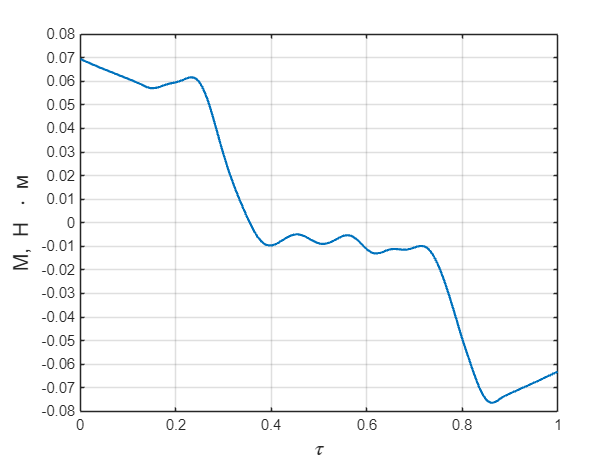


figure
plot(t,a/50 * 0.005, "LineWidth",1.5);
grid on
xlabel('$\tau$','Interpreter','latex','FontSize',14)
ylabel("M, Н \cdot м", "FontSize",14)
yticks(-0.08:0.01:0.08)
print(gcf, '../img/oy-gyro-mom.png', '-dpng', '-r600')